# Lab 3 IMU Bag A Analysis

Tha bag I was assigned to analyze was bag A. This is done below

clear
clc

bagA = rosbag("LocationA.bag");





bSel_A = select(bagA, 'Topic', '/vectornav');
msgStructs_A = readMessages(bSel_A,"DataFormat","struct");
time_secs_A = double(cellfun(@(m) m.Header.Stamp.Sec,msgStructs_A));
time_nsecs_A = double(cellfun(@(m) double(m.Header.Stamp.Nsec),msgStructs_A));

time_A = time_secs_A + (time_nsecs_A * 10^-9);
time_A = time_A - time_A(1);



VNYMR_A = cellfun(@(m) m.Data, msgStructs_A,'UniformOutput',false);
VNYMRstrings_A = string(VNYMR_A);

Data_A = zeros(length(VNYMR_A),12);
for i=1:length(VNYMR_A)
    A = split(VNYMRstrings_A(i),"*");
    B_X = split(A(1),",");
    C = B_X(2:length(B_X));
    C = double(C);
    Data_A(i,:) = C';
end

% converting magnetometer values from units of gauss to units of tesla
Data_A(:,4:6) = Data_A(:,4:6) * 10^-4;

%{
The above loop fills Data_A array such that each row contains an imu msg's
data. They are in order (correspond to time). The columns of each variable
correspond to
C1 - Yaw
C2 - Pitch
C3 - Roll
    above in degrees, these are the Euler angles
C4 - MagX
C5 - MagY
C6 - MagZ
    above initially in Gauss, converted to Tesla beneath for loop (1Gauss *
    10^-4 = 1 Tesla
C7 - AccelX
C8 - AccelY
C9 - AccelZ
    above in m/s^2
C10 - GyroX
C11 - GyroY
C12 - GyroZ
    above in rad/s

%}


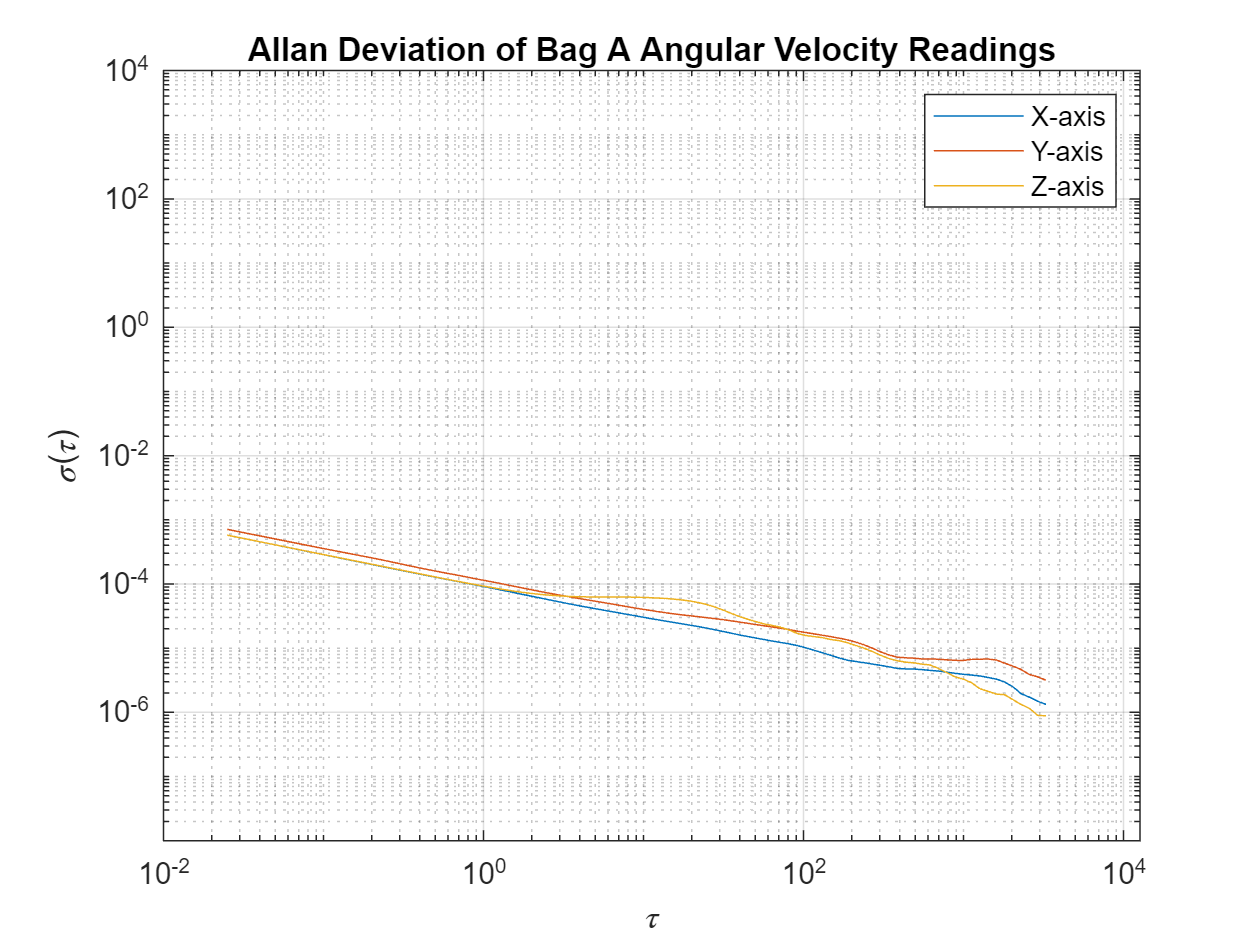

% Allan Variance plots of gyroscope's angular velocity readings (Fig 4)




% gyroscope axis readings already saved by previous section

% below is frequency (Hz) of sampling rate. However, my slow laptop
% required filtering out erroneous serial port messages (erroneous since
% computer couldn't keep up to speed), so it's not a 1:1 match between num
% of data points and doing 40instances/sec*Xsecondsinduration. So I'll have
% to be conscious of how this could impact results
GyroX_A = Data_A(:,10);
GyroY_A = Data_A(:,11);
GyroZ_A = Data_A(:,12);

freq = 40; 
t0 = 1/freq;

%%%%
thetaX_A = cumsum(GyroX_A,1)*t0;

%%%%
maxNumM = 100;

L_X = size(thetaX_A, 1);%%%%%%%%%
maxM_X = 2.^floor(log2(L_X/2));
m_X = logspace(log10(1), log10(maxM_X), maxNumM).';
m_X = ceil(m_X); % m must be an integer.
m_X = unique(m_X); % Remove duplicates.

tau_X = m_X*t0;

avar_X = zeros(numel(m_X), 1);
for i = 1:numel(m_X)
    mi_X = m_X(i);
    avar_X(i,:) = sum((thetaX_A(1+2*mi_X:L_X) - 2*thetaX_A(1+mi_X:L_X-mi_X) + thetaX_A(1:L_X-2*mi_X)).^2, 1);%%%%%%%
end
avar_X = avar_X ./ (2*tau_X.^2 .* (L_X - 2*m_X));

adev_X = sqrt(avar_X);

figure
loglog(tau_X, adev_X)
title('Allan Deviation of Bag A Angular Velocity Readings')
xlabel('\tau');
ylabel('\sigma(\tau)')
grid on
axis equal
hold on
%%%%%

thetaY_A = cumsum(GyroY_A,1)*t0;

L_Y = size(thetaY_A, 1);%%%%%%%%%
maxM_Y = 2.^floor(log2(L_Y/2));
m_Y = logspace(log10(1), log10(maxM_Y), maxNumM).';
m_Y = ceil(m_Y); % m must be an integer.
m_Y = unique(m_Y); % Remove duplicates.

tau_Y = m_Y*t0;

avar_Y = zeros(numel(m_Y), 1);
for i = 1:numel(m_Y)
    mi_Y = m_Y(i);
    avar_Y(i,:) = sum((thetaY_A(1+2*mi_Y:L_Y) - 2*thetaY_A(1+mi_Y:L_Y-mi_Y) + thetaY_A(1:L_Y-2*mi_Y)).^2, 1);%%%%%%%
end
avar_Y = avar_Y ./ (2*tau_Y.^2 .* (L_Y - 2*m_Y));

adev_Y = sqrt(avar_Y);

%figure
loglog(tau_Y, adev_Y)
%title('Allan Deviation of Bag A GyroY')
%xlabel('\tau');
%ylabel('\sigma(\tau)')
%grid on
%axis equal


%%%%%%%%%%%%%%%5
thetaZ_A = cumsum(GyroZ_A,1)*t0;

L_Z = size(thetaZ_A, 1);%%%%%%%%%
maxM_Z= 2.^floor(log2(L_Z/2));
m_Z = logspace(log10(1), log10(maxM_Z), maxNumM).';
m_Z = ceil(m_Z); % m must be an integer.
m_Z = unique(m_Z); % Remove duplicates.

tau_Z = m_Z*t0;

avar_Z = zeros(numel(m_Z), 1);
for i = 1:numel(m_Z)
    mi_Z = m_Z(i);
    avar_Z(i,:) = sum((thetaZ_A(1+2*mi_Z:L_Z) - 2*thetaZ_A(1+mi_Z:L_Z-mi_Z) + thetaZ_A(1:L_Z-2*mi_Z)).^2, 1);%%%%%%%
end
avar_Z = avar_Z ./ (2*tau_Z.^2 .* (L_Z - 2*m_Z));

adev_Z = sqrt(avar_Z);

%figure
loglog(tau_Z, adev_Z)
%title('Allan Deviation of Bag A GyroZ')
%xlabel('\tau');
%ylabel('\sigma(\tau)')
%grid on
%axis equal
hold off
legend('X-axis','Y-axis','Z-axis')



%%%% angle random walk (N) below


%%%%%%%%%%%%%%%%%%%%%%%%%%%%% below for X-axis random walk
% Find the index where the slope of the log-scaled Allan deviation is equal
% to the slope specified.
slopeN = -0.5;
logtau_X = log10(tau_X);
logadev_X = log10(adev_X);
dlogadev_X = diff(logadev_X) ./ diff(logtau_X);
[~, i] = min(abs(dlogadev_X - slopeN));

% Find the y-intercept of the line.
b_X = logadev_X(i) - slopeN*logtau_X(i);

% Determine the angle random walk coefficient from the line.
logN_X = slopeN*log(1) + b_X;
N_X = 10^logN_X

N_X = 9.0084e-05

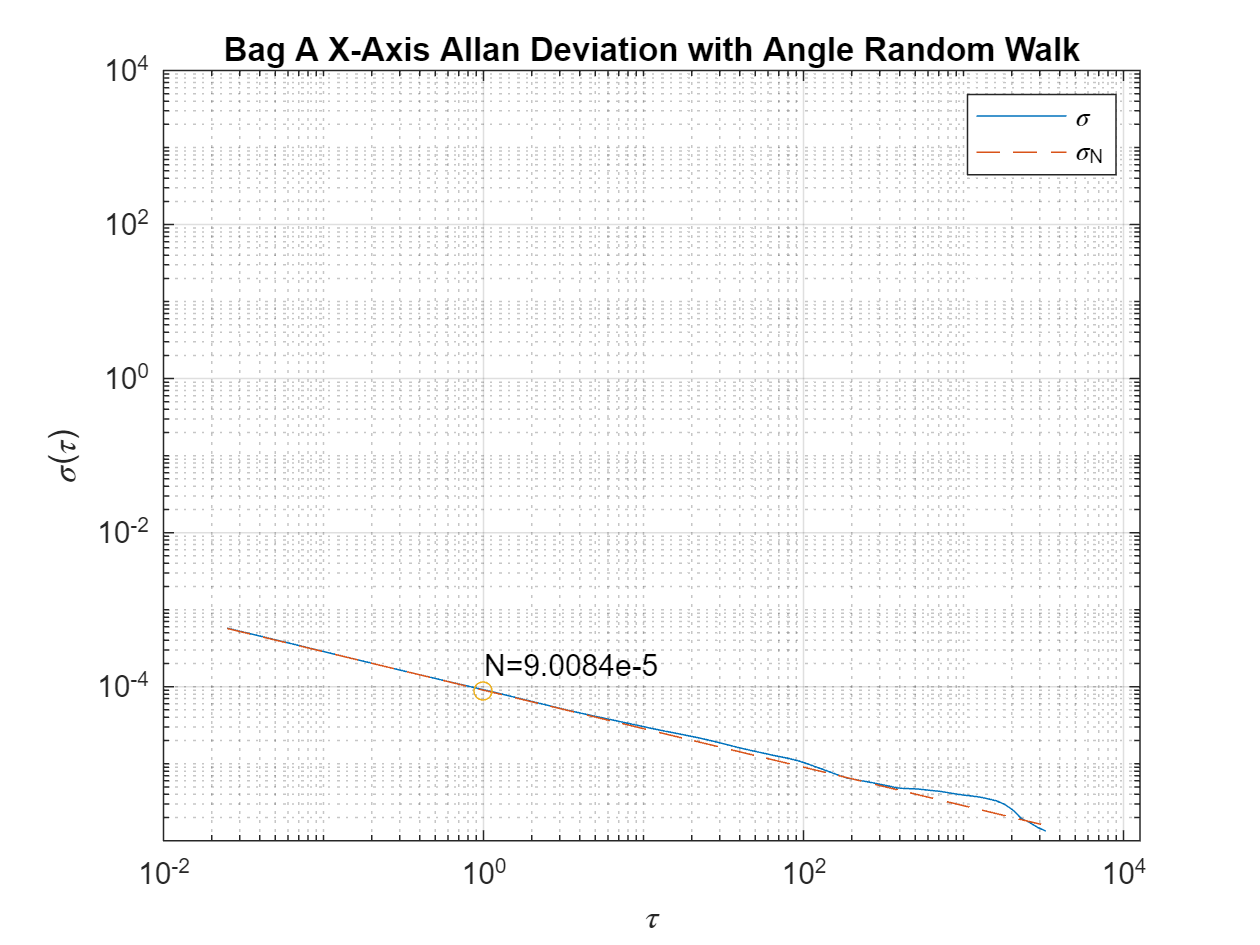


% Plot the results.
tauN_X = 1;
lineN_X = N_X ./ sqrt(tau_X);
figure
loglog(tau_X, adev_X, tau_X, lineN_X, '--', tauN_X, N_X, 'o')
title('Bag A X-Axis Allan Deviation with Angle Random Walk')
xlabel('\tau')
ylabel('\sigma(\tau)')
legend('\sigma', '\sigma_N')
text(tauN_X, N_X+.0001, 'N=9.0084e-5')
grid on
axis equal



%%%%%%%%%%%%%%%%%%%%%%%%%%%%% below for Y-axis random walk
slopeN = -0.5;
logtau_Y = log10(tau_Y);
logadev_Y = log10(adev_Y);
dlogadev_Y = diff(logadev_Y) ./ diff(logtau_Y);
[~, i] = min(abs(dlogadev_Y - slopeN));

% Find the y-intercept of the line.
b_Y = logadev_Y(i) - slopeN*logtau_Y(i);

% Determine the angle random walk coefficient from the line.
logN_Y = slopeN*log(1) + b_Y;
N_Y = 10^logN_Y

N_Y = 1.1251e-04

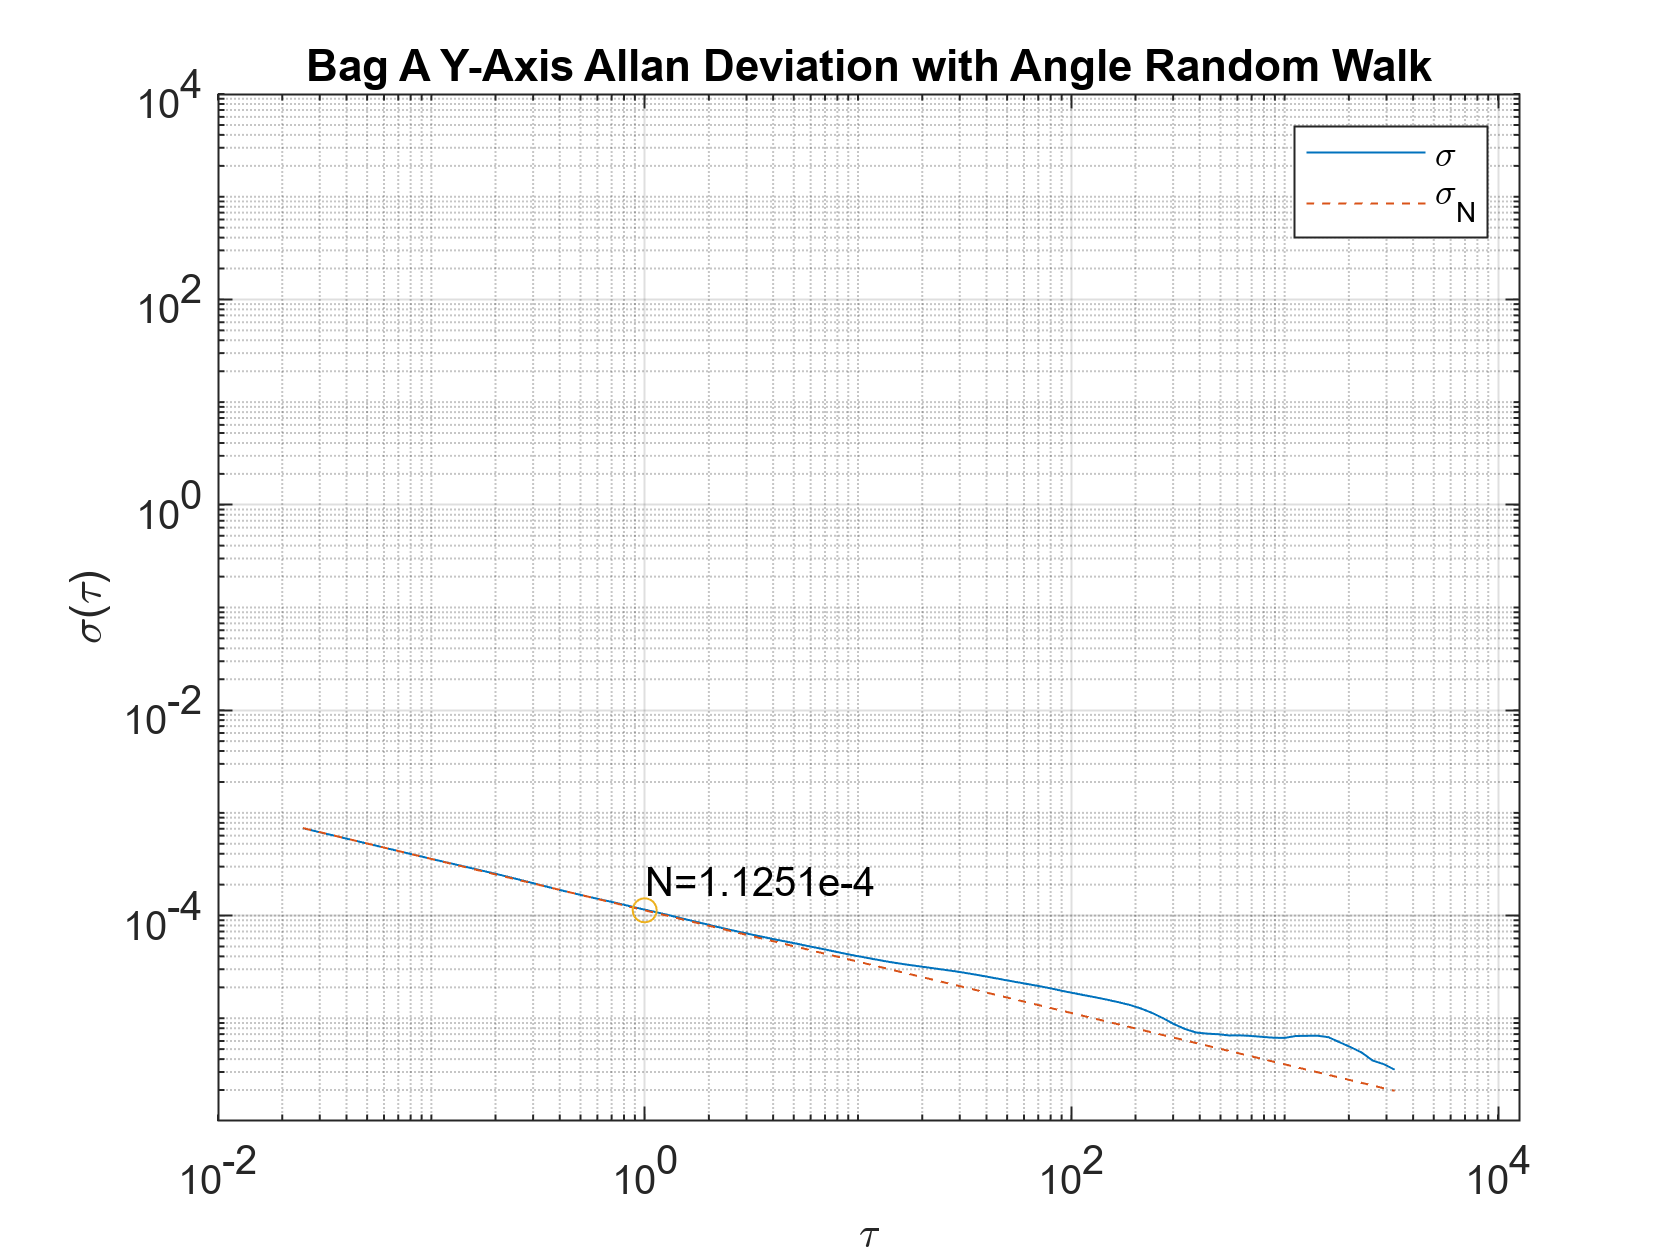


% Plot the results.
tauN_Y = 1;
lineN_Y = N_Y ./ sqrt(tau_Y);
figure
loglog(tau_Y, adev_Y, tau_Y, lineN_Y, '--', tauN_Y, N_Y, 'o')
title('Bag A Y-Axis Allan Deviation with Angle Random Walk')
xlabel('\tau')
ylabel('\sigma(\tau)')
legend('\sigma', '\sigma_N')
text(tauN_Y, N_Y+.0001, 'N=1.1251e-4')
grid on
axis equal




%%%%%%%%%%%%%%%%%%%%%%%%%%%%% below for Z-axis random walk
slopeN = -0.5;
logtau_Z = log10(tau_Z);
logadev_Z = log10(adev_Z);
dlogadev_Z = diff(logadev_Z) ./ diff(logtau_Z);
[~, i] = min(abs(dlogadev_Z - slopeN));

% Find the y-intercept of the line.
b_Z = logadev_Z(i) - slopeN*logtau_Z(i);

% Determine the angle random walk coefficient from the line.
logN_Z = slopeN*log(1) + b_Z;
N_Z = 10^logN_Z

N_Z = 9.1164e-05

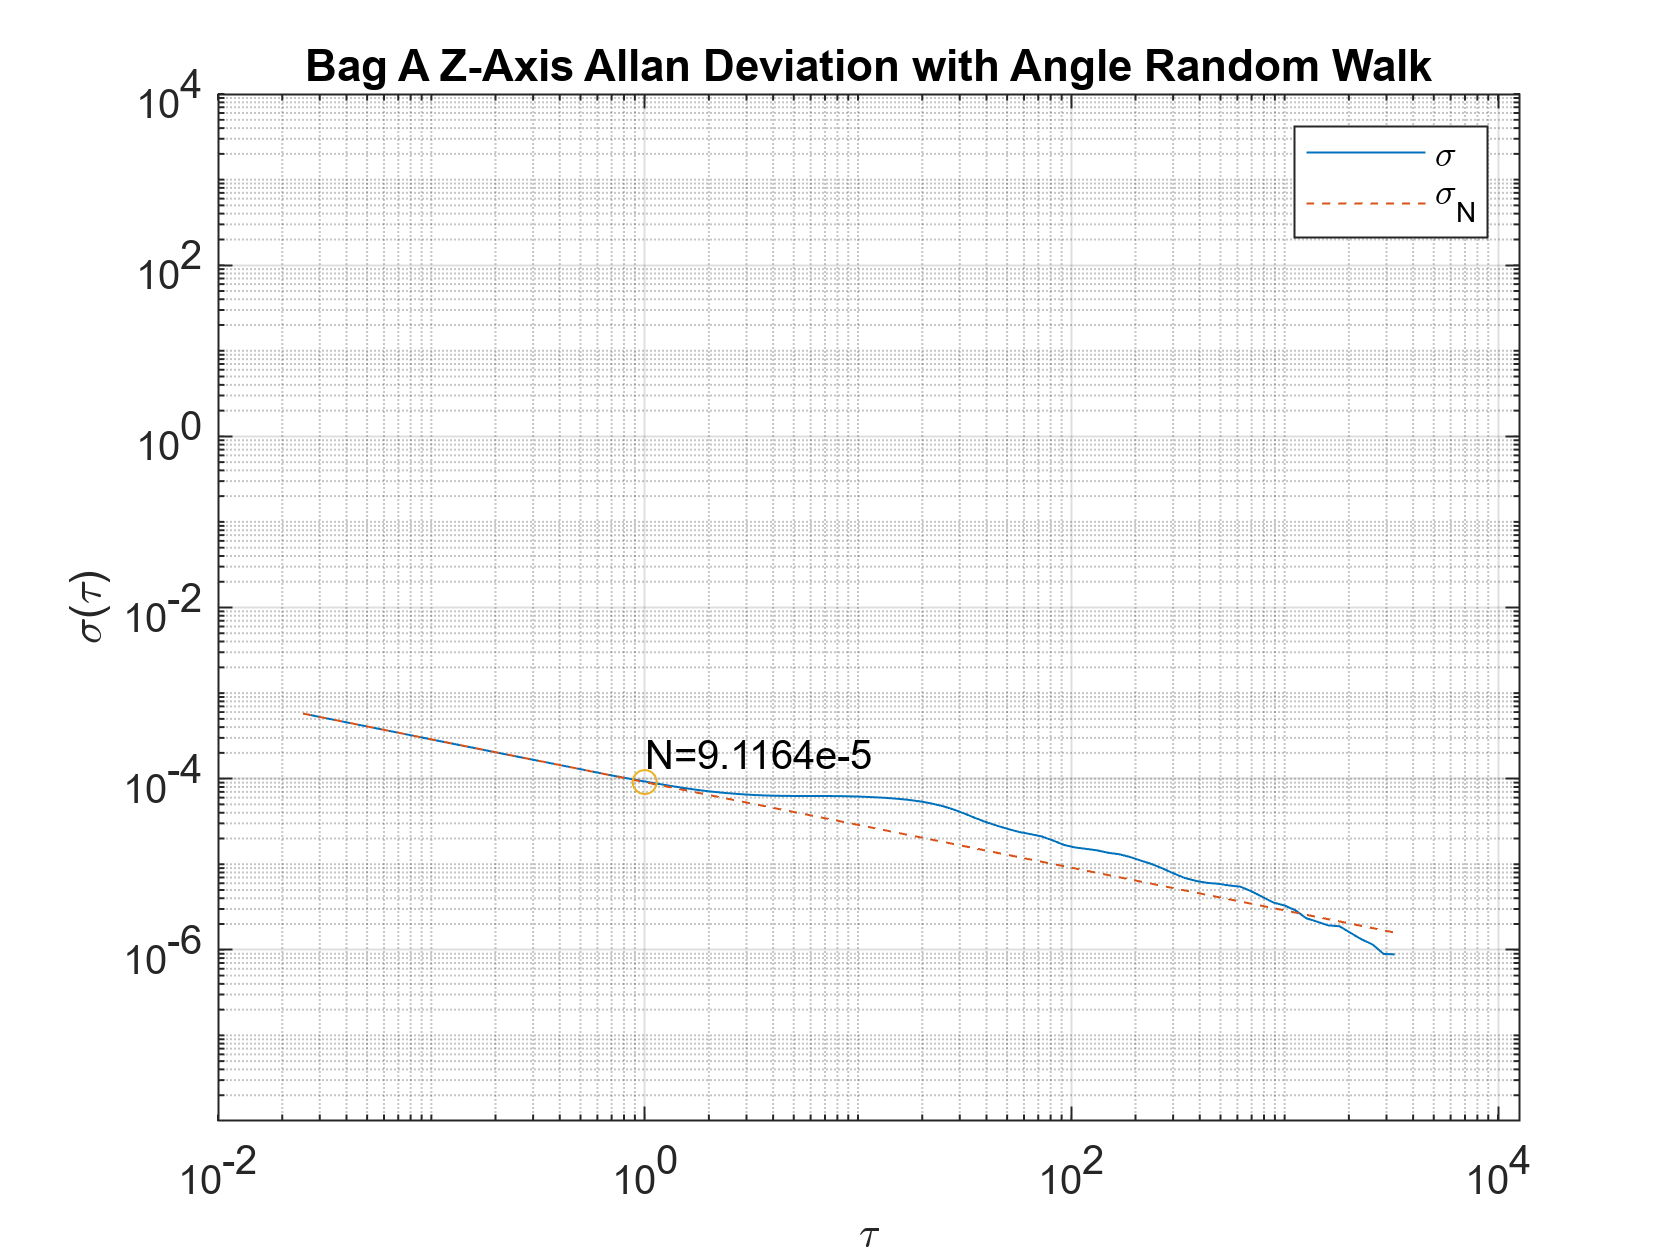


% Plot the results.
tauN_Z = 1;
lineN_Z = N_Z ./ sqrt(tau_Z);
figure
loglog(tau_Z, adev_Z, tau_Z, lineN_Z, '--', tauN_Z, N_Z, 'o')
title('Bag A Z-Axis Allan Deviation with Angle Random Walk')
xlabel('\tau')
ylabel('\sigma(\tau)')
legend('\sigma', '\sigma_N')
text(tauN_Z, N_Z+.0001, 'N=9.1164e-5')
grid on
axis equal


%%%%%%%% Rate Random Walk (K) below

%%%%%%%%%%%%%%%%%%%%%%% x-axis random walk below
% Find the index where the slope of the log-scaled Allan deviation is equal
% to the slope specified.
slopeK = 0.5;
logtauK_X = log10(tau_X);
logadevK_X = log10(adev_X);
dlogadevK_X = diff(logadevK_X) ./ diff(logtauK_X);
[~, i] = min(abs(dlogadevK_X - slopeK));

% Find the y-intercept of the line.
bK_X = logadevK_X(i) - slopeK*logtauK_X(i);

% Determine the rate random walk coefficient from the line.
logK_X = slopeK*log10(3) + bK_X;
K_X = 10^logK_X

K_X = 3.9555e-07

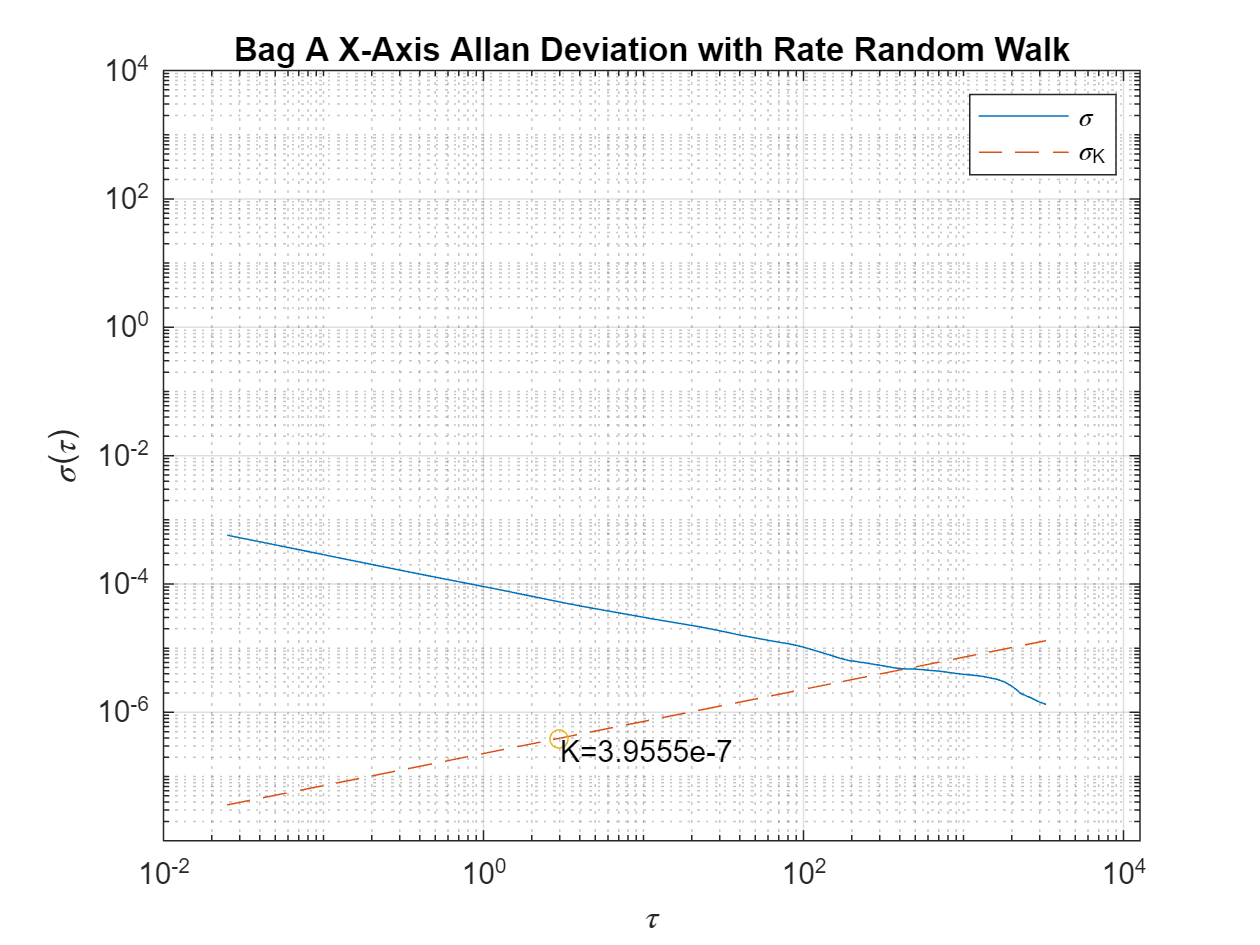


% Plot the results.
tauK_X = 3;
lineK_X = K_X .* sqrt(tau_X/3);
figure
loglog(tau_X, adev_X, tau_X, lineK_X, '--', tauK_X, K_X, 'o')
title('Bag A X-Axis Allan Deviation with Rate Random Walk')
xlabel('\tau')
ylabel('\sigma(\tau)')
legend('\sigma', '\sigma_K')
text(tauK_X, K_X-0.00000015, 'K=3.9555e-7')
grid on
axis equal



%%%%%%%%%%%%%%%%%%%%%%%%%%%% y-axis random walk below
% Find the index where the slope of the log-scaled Allan deviation is equal
% to the slope specified.
slopeK = 0.5;
logtauK_Y = log10(tau_Y);
logadevK_Y = log10(adev_Y);
dlogadevK_Y = diff(logadevK_Y) ./ diff(logtauK_Y);
[~, i] = min(abs(dlogadevK_Y - slopeK));

% Find the y-intercept of the line.
bK_Y = logadevK_Y(i) - slopeK*logtauK_Y(i);

% Determine the rate random walk coefficient from the line.
logK_Y = slopeK*log10(3) + bK_Y;
K_Y = 10^logK_Y

K_Y = 3.5289e-07

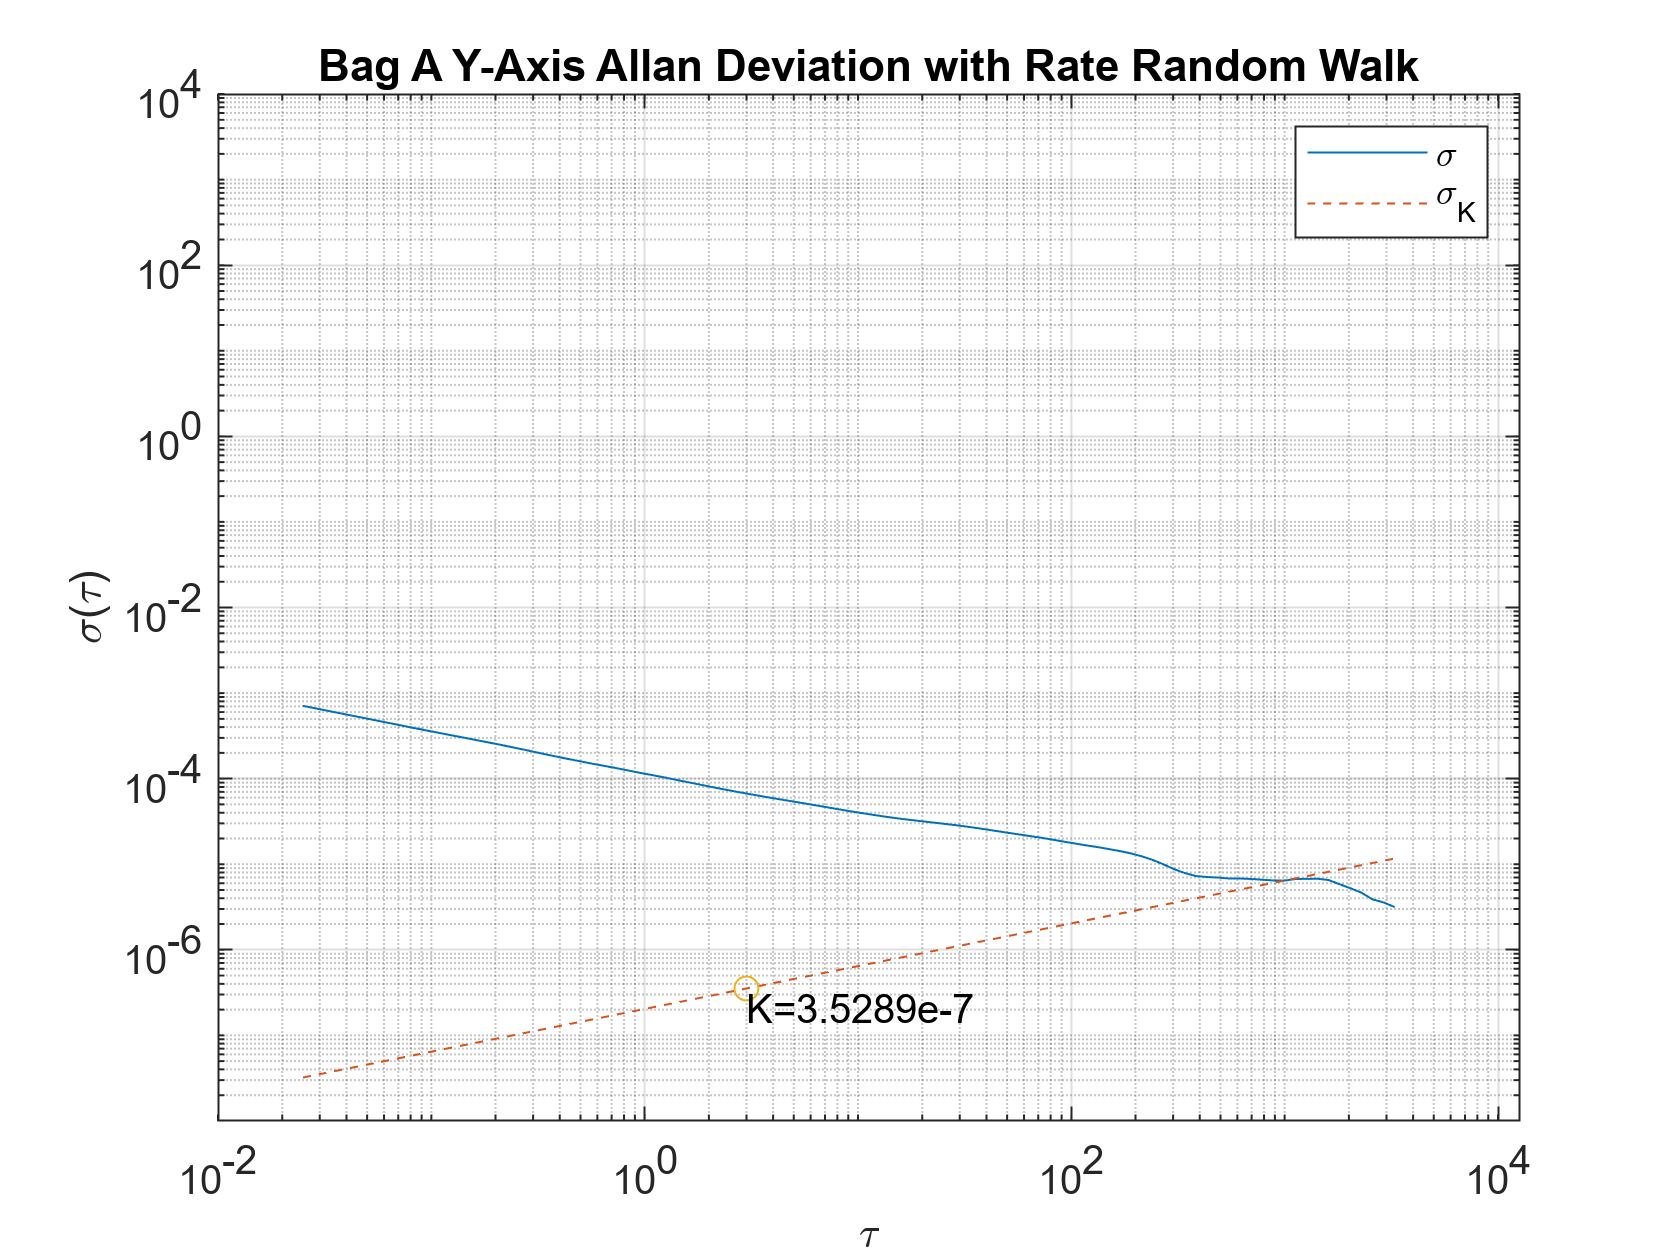


% Plot the results.
tauK_Y = 3;
lineK_Y = K_Y .* sqrt(tau_Y/3);
figure
loglog(tau_Y, adev_Y, tau_Y, lineK_Y, '--', tauK_Y, K_Y, 'o')
title('Bag A Y-Axis Allan Deviation with Rate Random Walk')
xlabel('\tau')
ylabel('\sigma(\tau)')
legend('\sigma', '\sigma_K')
text(tauK_Y, K_Y-0.00000015, 'K=3.5289e-7')
grid on
axis equal



%%%%%%%%%%%%%%%%%%%%%%% z-axis random walk below
% Find the index where the slope of the log-scaled Allan deviation is equal
% to the slope specified.
slopeK = 0.5;
logtauK_Z = log10(tau_Z);
logadevK_Z = log10(adev_Z);
dlogadevK_Z = diff(logadevK_Z) ./ diff(logtauK_Z);
[~, i] = min(abs(dlogadevK_Z - slopeK));

% Find the y-intercept of the line.
bK_Z = logadevK_Z(i) - slopeK*logtauK_Z(i);

% Determine the rate random walk coefficient from the line.
logK_Z = slopeK*log10(3) + bK_Z;
K_Z = 10^logK_Z

K_Z = 4.7209e-05

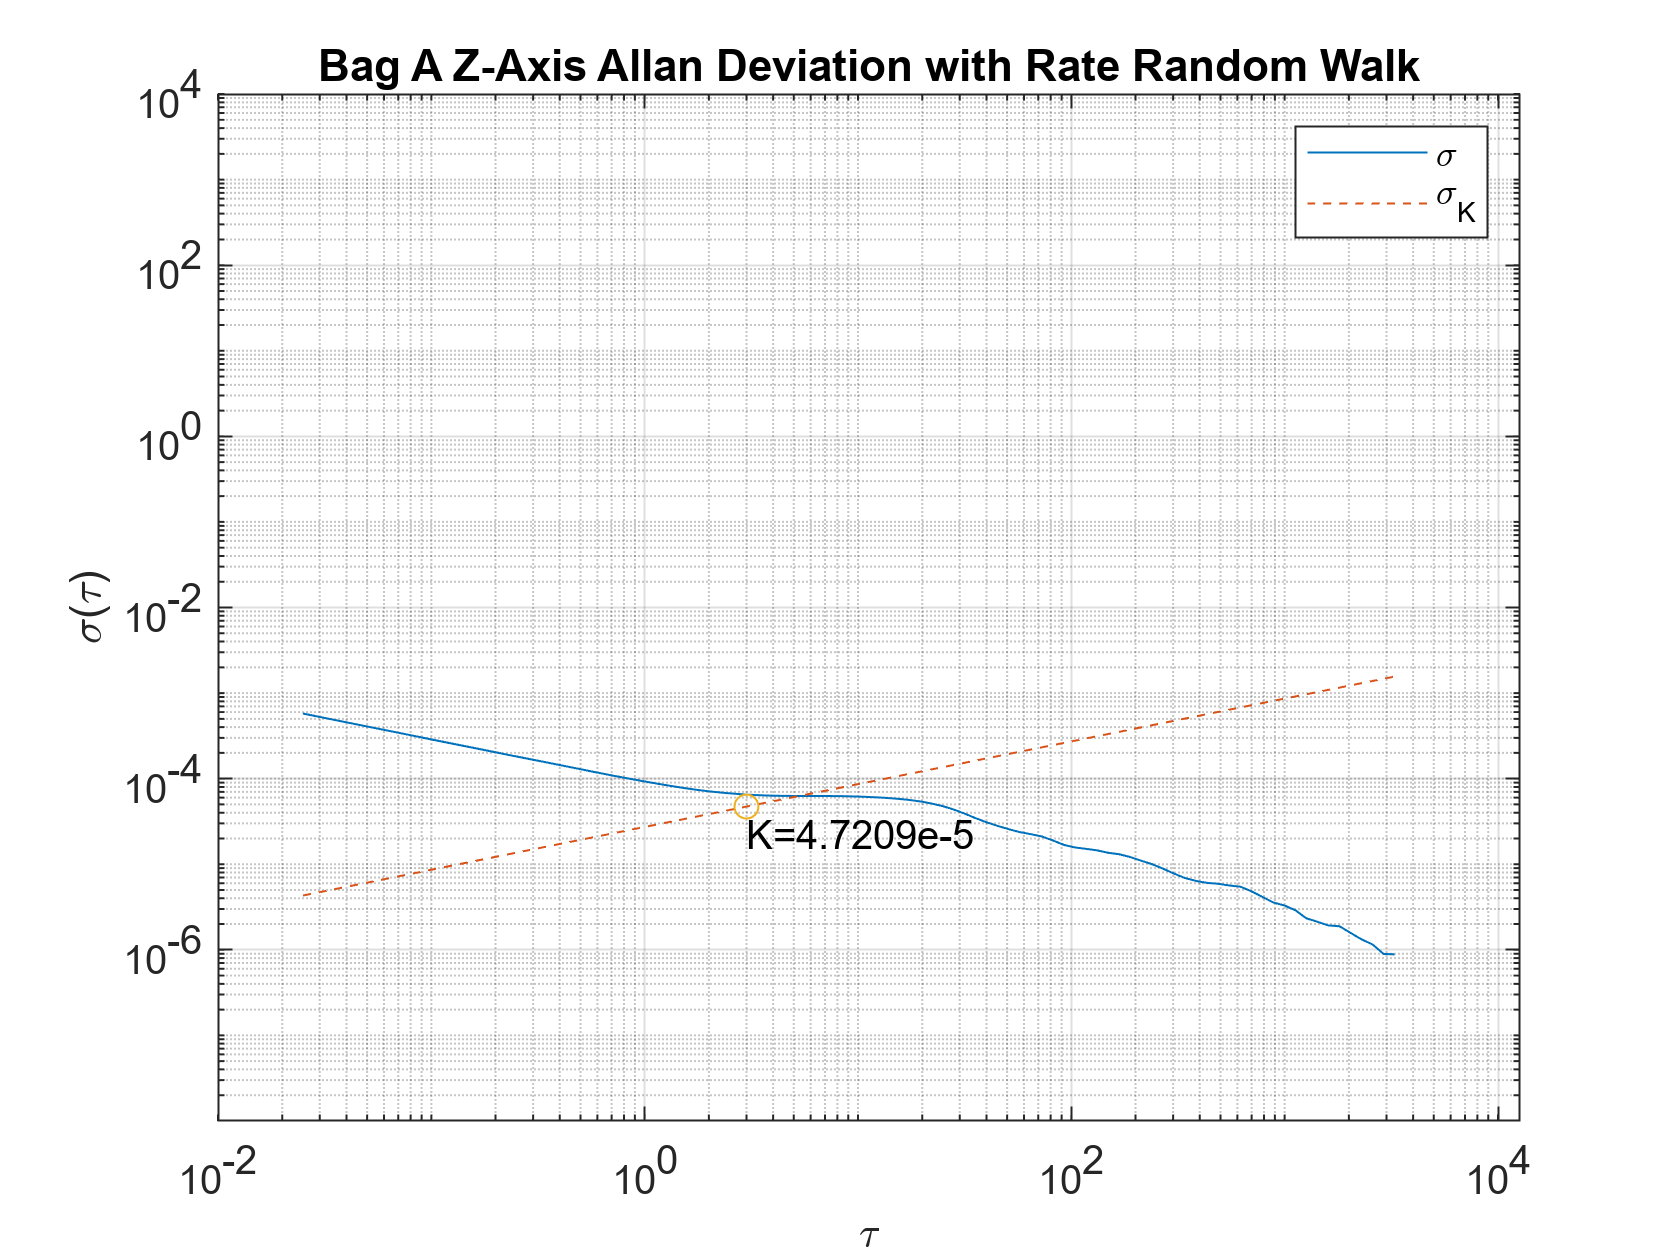


% Plot the results.
tauK_Z = 3;
lineK_Z = K_Z .* sqrt(tau_Z/3);
figure
loglog(tau_Z, adev_Z, tau_Z, lineK_Z, '--', tauK_Z, K_Z, 'o')
title('Bag A Z-Axis Allan Deviation with Rate Random Walk')
xlabel('\tau')
ylabel('\sigma(\tau)')
legend('\sigma', '\sigma_K')
text(tauK_Z, K_Z-0.000025, 'K=4.7209e-5')
grid on
axis equal


%%%%%%%% Bias Instability (B) below


%%%%%%%%%%%%%%%%%%%%% x-axis bias instability below

% Find the index where the slope of the log-scaled Allan deviation is equal
% to the slope specified.

slopeB = 0;
logtauB_X = log10(tau_X);
logadevB_X = log10(adev_X);
dlogadevB_X = diff(logadevB_X) ./ diff(logtauB_X);
[~, i] = min(abs(dlogadevB_X - slopeB));

% Find the y-intercept of the line.
bB_X = logadevB_X(i) - slopeB*logtauB_X(i);

% Determine the bias instability coefficient from the line.
scfB_X = sqrt(2*log(2)/pi);
logB_X = bB_X - log10(scfB_X);
B_X = 10^logB_X

B_X = 7.1553e-06

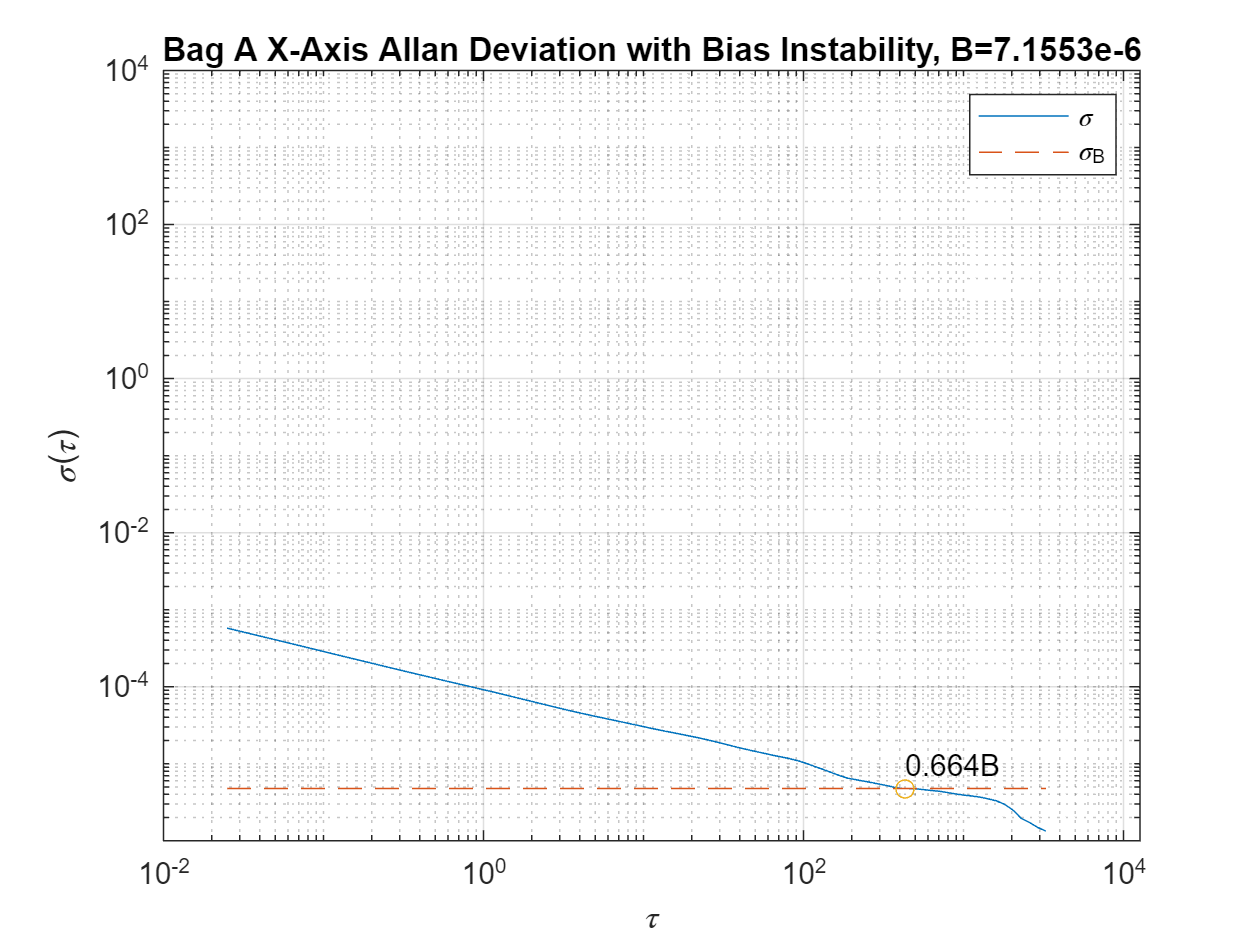




% Plot the results.
tauB_X = tau_X(i);
lineB_X = B_X * scfB_X * ones(size(tau_X));
figure
loglog(tau_X, adev_X, tau_X, lineB_X, '--', tauB_X, scfB_X*B_X, 'o')
title('Bag A X-Axis Allan Deviation with Bias Instability, B=7.1553e-6')
xlabel('\tau')
ylabel('\sigma(\tau)')
legend('\sigma', '\sigma_B')
text(tauB_X, (scfB_X*B_X)+.000005, '0.664B')
grid on
axis equal



%%%%%%%%%%%%%%%%%%%%% y-axis bias instability below

% Find the index where the slope of the log-scaled Allan deviation is equal
% to the slope specified.
slopeB = 0;
logtauB_Y = log10(tau_Y);
logadevB_Y = log10(adev_Y);
dlogadevB_Y = diff(logadevB_Y) ./ diff(logtauB_Y);
[~, i] = min(abs(dlogadevB_Y - slopeB));

% Find the y-intercept of the line.
bB_Y = logadevB_Y(i) - slopeB*logtauB_Y(i);

% Determine the bias instability coefficient from the line.
scfB_Y = sqrt(2*log(2)/pi);
logB_Y = bB_Y - log10(scfB_Y);
B_Y = 10^logB_Y

B_Y = 1.0239e-05

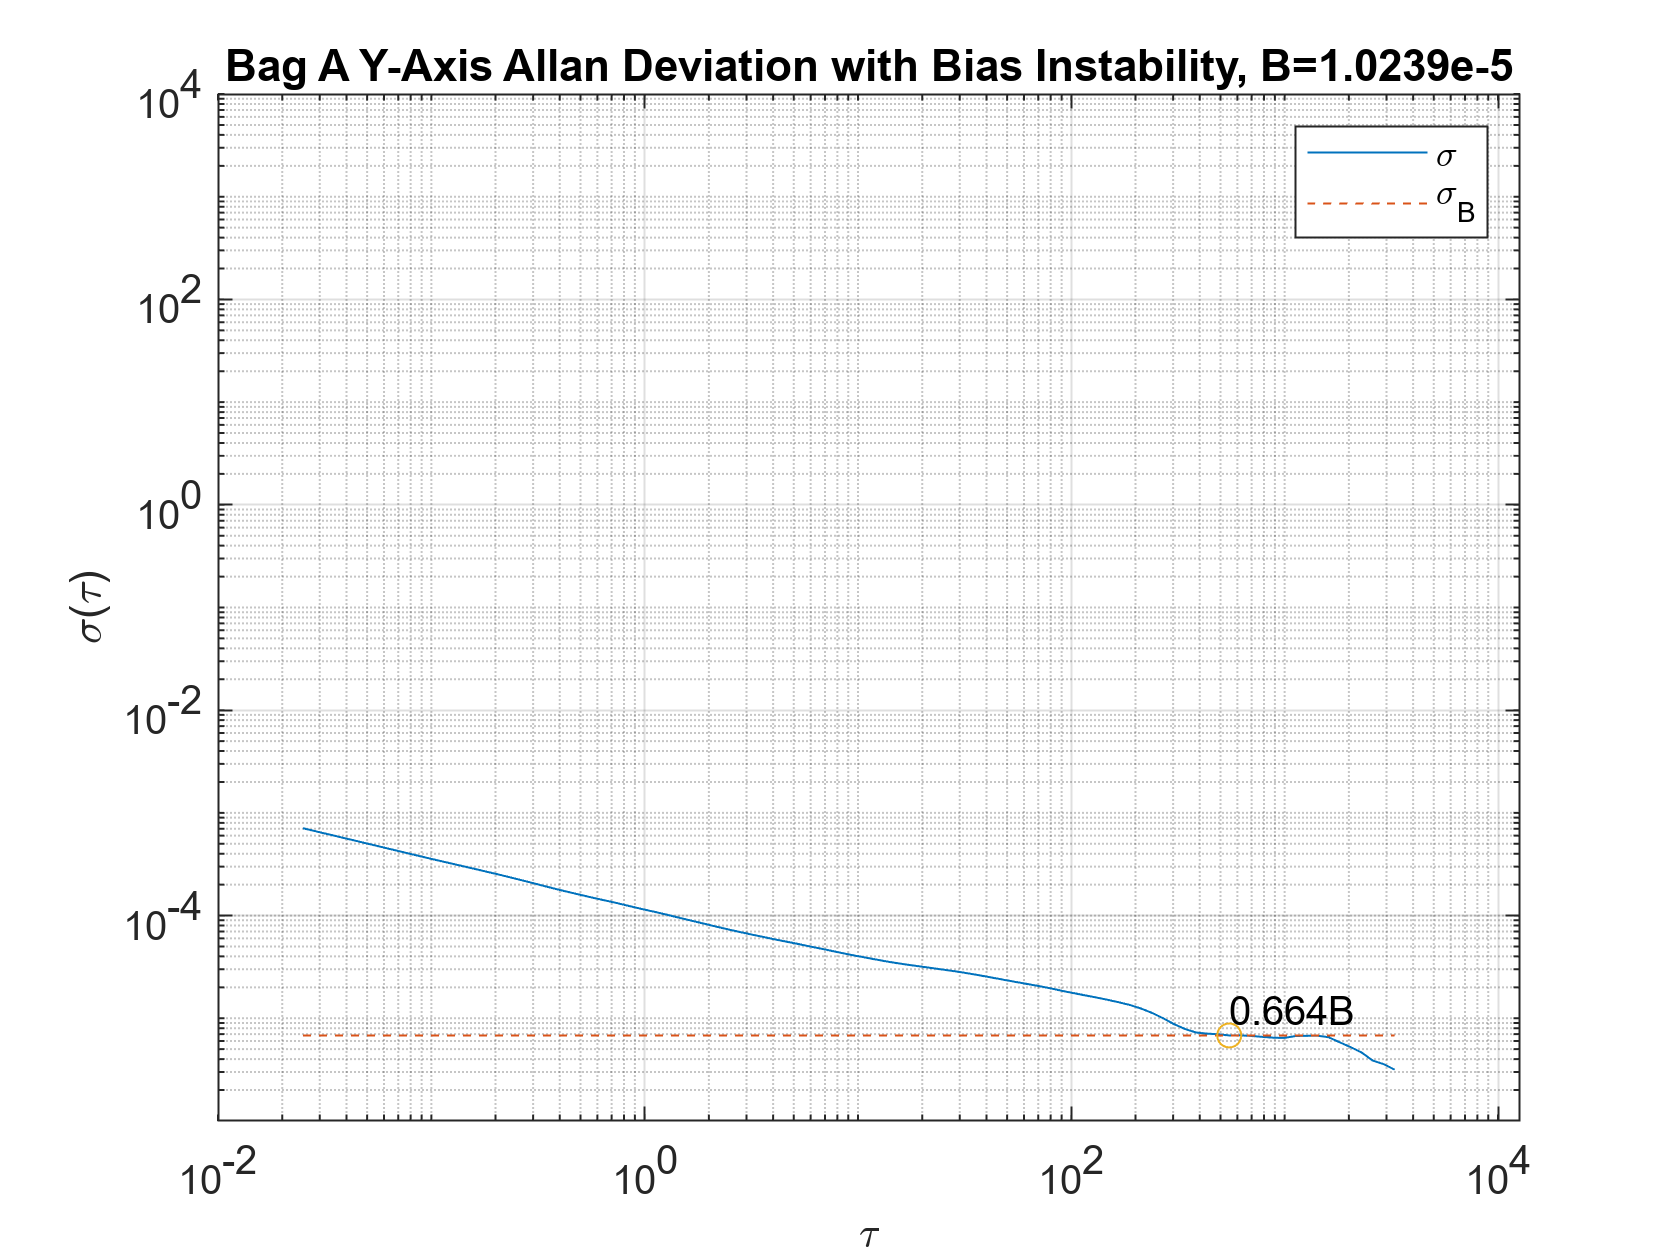




% Plot the results.
tauB_Y = tau_Y(i);
lineB_Y = B_Y * scfB_Y * ones(size(tau_Y));
figure
loglog(tau_Y, adev_Y, tau_Y, lineB_Y, '--', tauB_Y, scfB_Y*B_Y, 'o')
title('Bag A Y-Axis Allan Deviation with Bias Instability, B=1.0239e-5')
xlabel('\tau')
ylabel('\sigma(\tau)')
legend('\sigma', '\sigma_B')
text(tauB_Y, (scfB_Y*B_Y)+.000005, '0.664B')
grid on
axis equal



%%%%%%%%%%%%%%%%%%%%% z-axis bias instability below

% Find the index where the slope of the log-scaled Allan deviation is equal
% to the slope specified.
slopeB = 0;
logtauB_Z = log10(tau_Z);
logadevB_Z = log10(adev_Z);
dlogadevB_Z = diff(logadevB_Z) ./ diff(logtauB_Z);
[~, i] = min(abs(dlogadevB_Z - slopeB));

% Find the y-intercept of the line.
bB_Z = logadevB_Z(i) - slopeB*logtauB_Z(i);

% Determine the bias instability coefficient from the line.
scfB_Z = sqrt(2*log(2)/pi);
logB_Z = bB_Z - log10(scfB_Z);
B_Z = 10^logB_Z

B_Z = 9.4460e-05

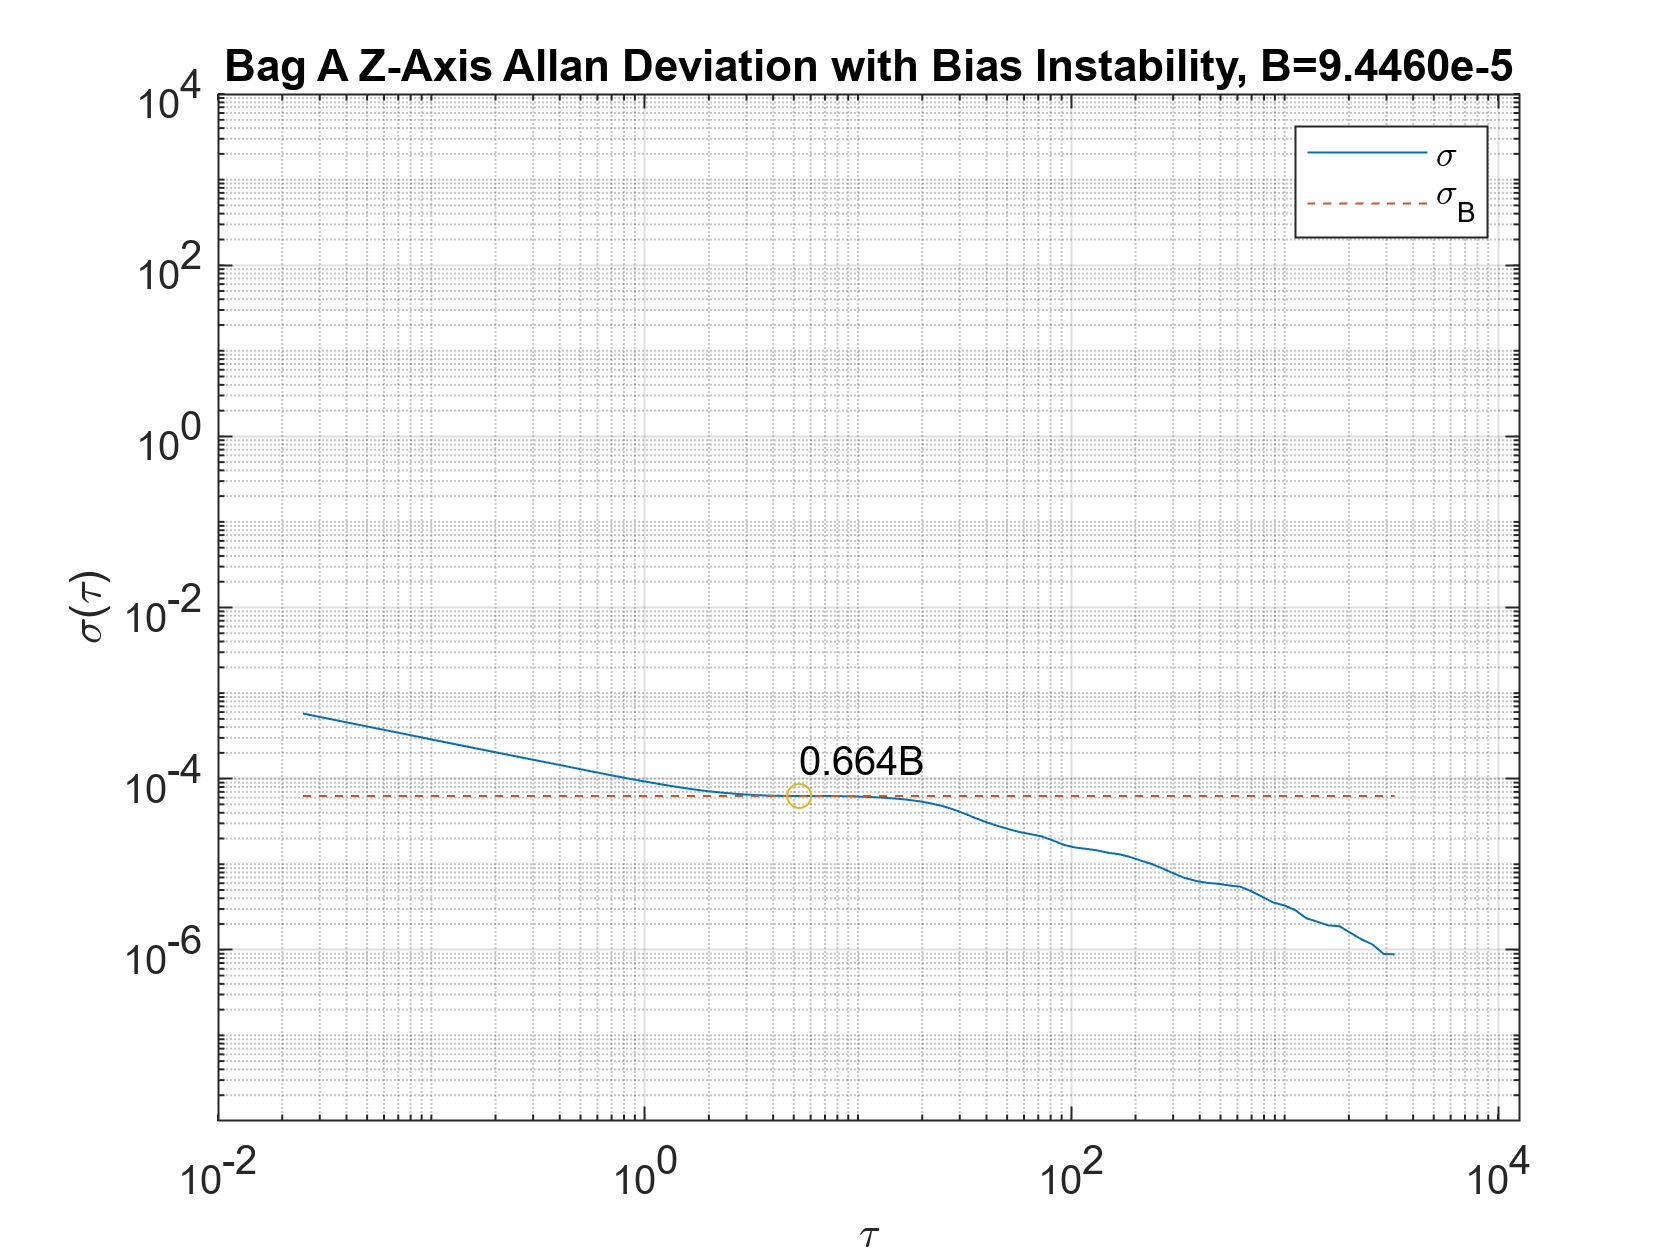




% Plot the results.
tauB_Z = tau_Z(i);
lineB_Z = B_Z * scfB_Z * ones(size(tau_Z));
figure
loglog(tau_Z, adev_Z, tau_Z, lineB_Z, '--', tauB_Z, scfB_Z*B_Z, 'o')
title('Bag A Z-Axis Allan Deviation with Bias Instability, B=9.4460e-5')
xlabel('\tau')
ylabel('\sigma(\tau)')
legend('\sigma', '\sigma_B')
text(tauB_Z, (scfB_Z*B_Z)+.0001, '0.664B')
grid on
axis equal

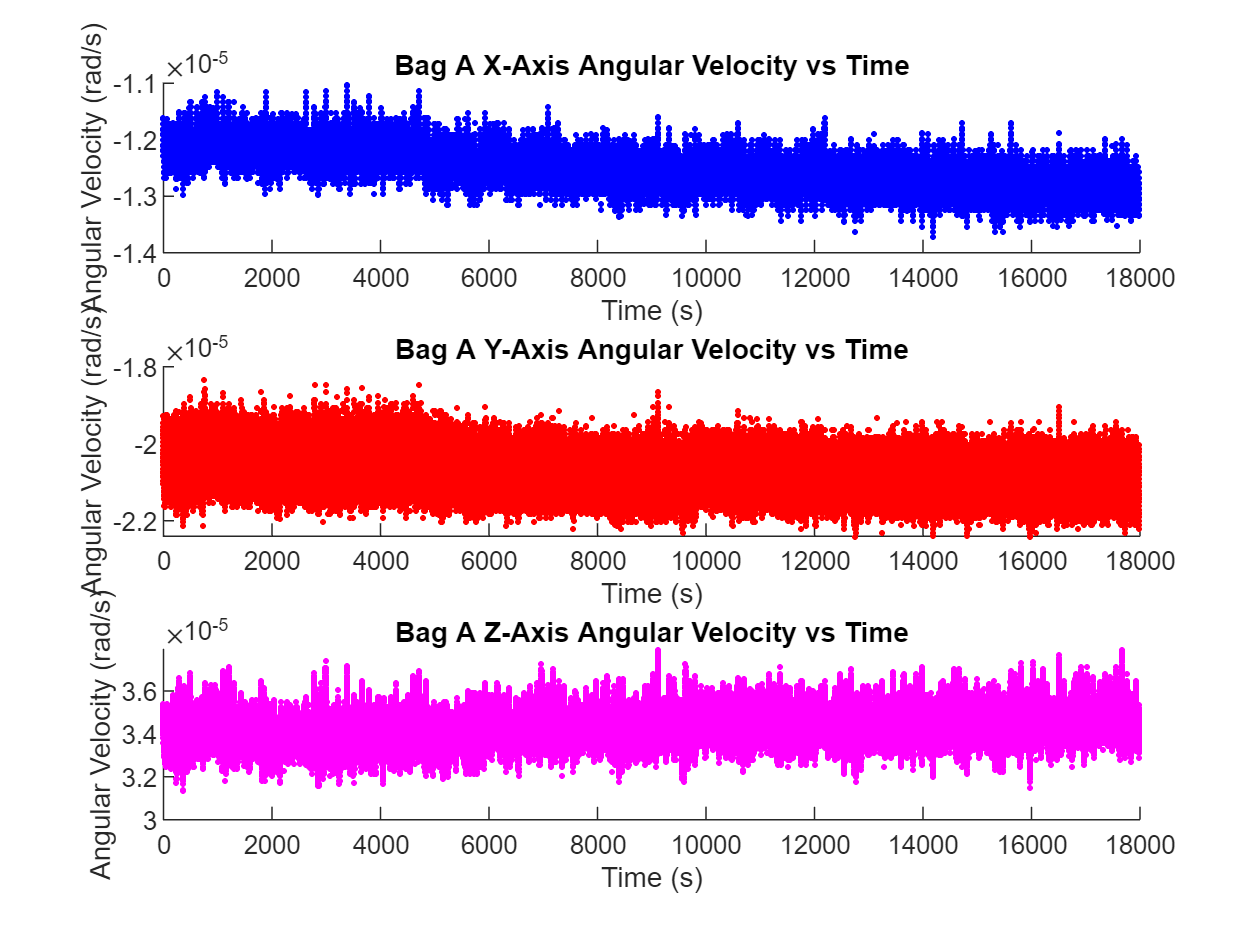



% below is the angular velocity (gyroscope) data for Bag A
subplot(3,1,1)
scatter(time_A,Data_A(:,4), '.','blue')
title("Bag A X-Axis Angular Velocity vs Time")
xlabel("Time (s)")
ylabel("Angular Velocity (rad/s)")

subplot(3,1,2)
scatter(time_A,Data_A(:,5), '.','red')
title("Bag A Y-Axis Angular Velocity vs Time")
xlabel("Time (s)")
ylabel("Angular Velocity (rad/s)")

subplot(3,1,3)
scatter(time_A,Data_A(:,6), '.','magenta')
title("Bag A Z-Axis Angular Velocity vs Time")
xlabel("Time (s)")
ylabel("Angular Velocity (rad/s)")

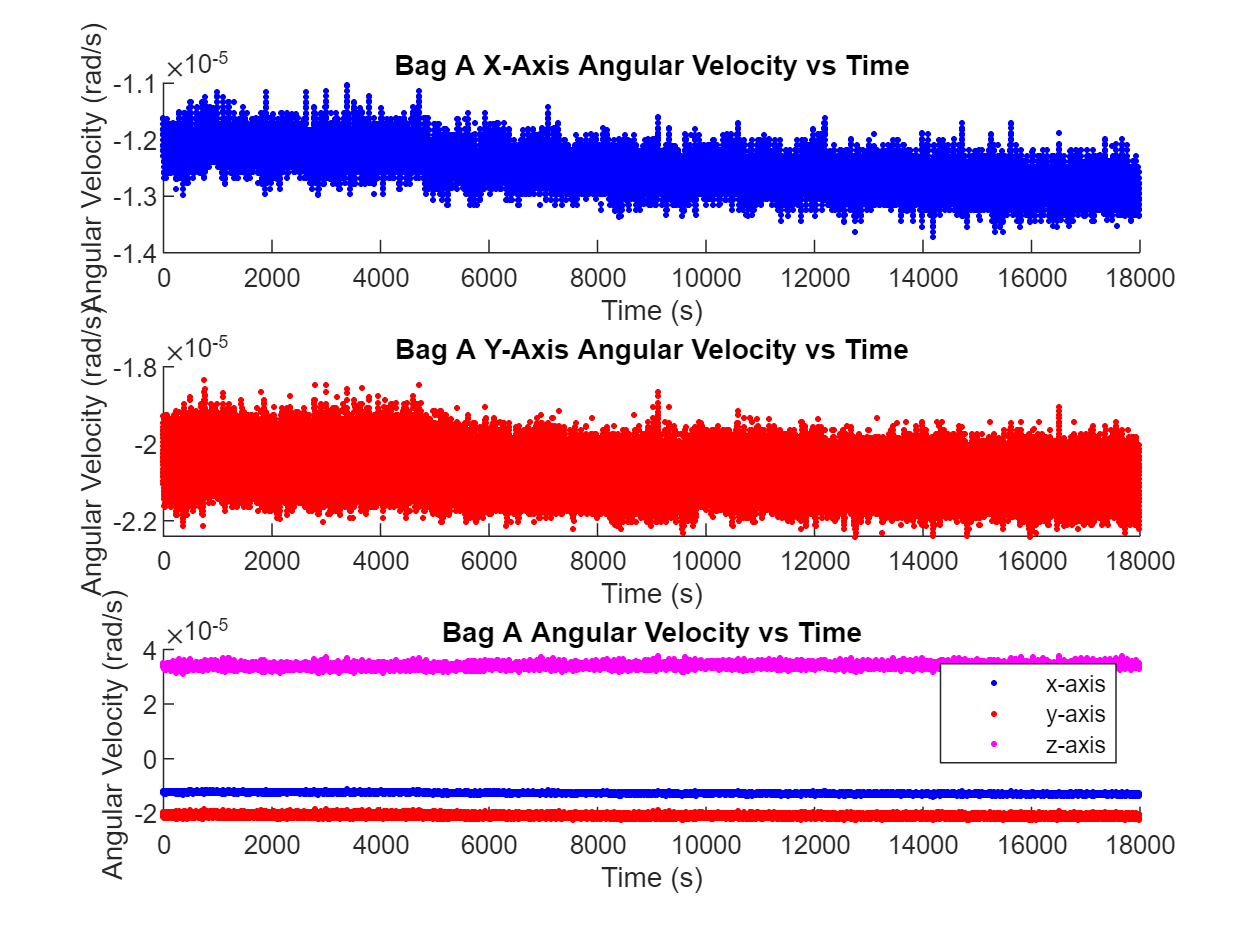

% angular velocity gyroscope vs time plot (Fig 5)



scatter(time_A,Data_A(:,4), '.','blue')
title("Bag A Angular Velocity vs Time")
xlabel("Time (s)")
ylabel("Angular Velocity (rad/s)")

hold on
scatter(time_A,Data_A(:,5), '.','red')

subplot(3,1,3)
scatter(time_A,Data_A(:,6), '.','magenta')

hold off
legend('x-axis','y-axis','z-axis')

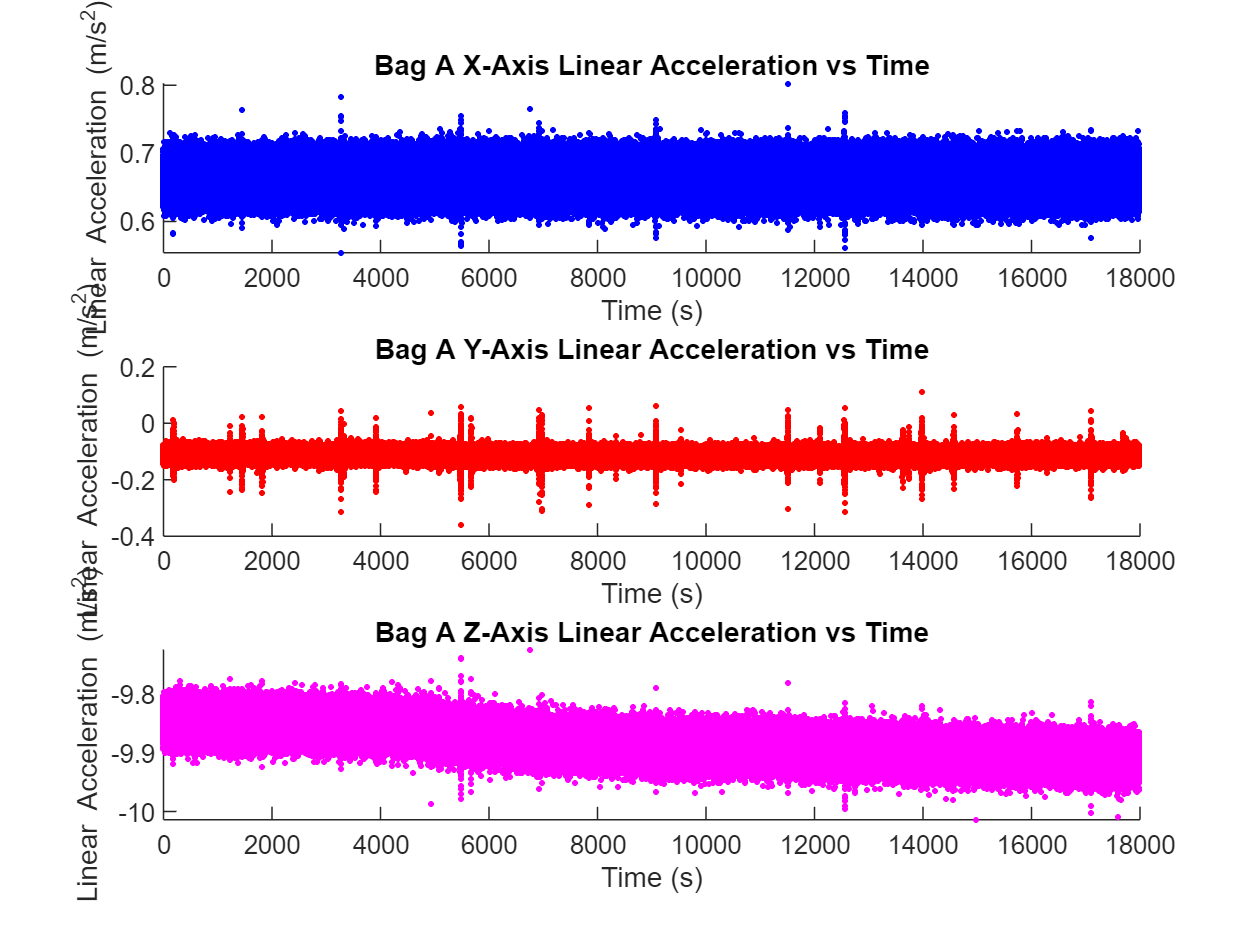

% below is the plotting for the linear acceleration data of bag A

subplot(3,1,1)
scatter(time_A,Data_A(:,7), '.','blue')
title("Bag A X-Axis Linear Acceleration vs Time")
xlabel("Time (s)")
ylabel("Linear Acceleration (m/s^2)")

subplot(3,1,2)
scatter(time_A,Data_A(:,8), '.','red')
title("Bag A Y-Axis Linear Acceleration vs Time")
xlabel("Time (s)")
ylabel("Linear Acceleration (m/s^2)")

subplot(3,1,3)
scatter(time_A,Data_A(:,9), '.','magenta')
title("Bag A Z-Axis Linear Acceleration vs Time")
xlabel("Time (s)")
ylabel("Linear Acceleration (m/s^2)")

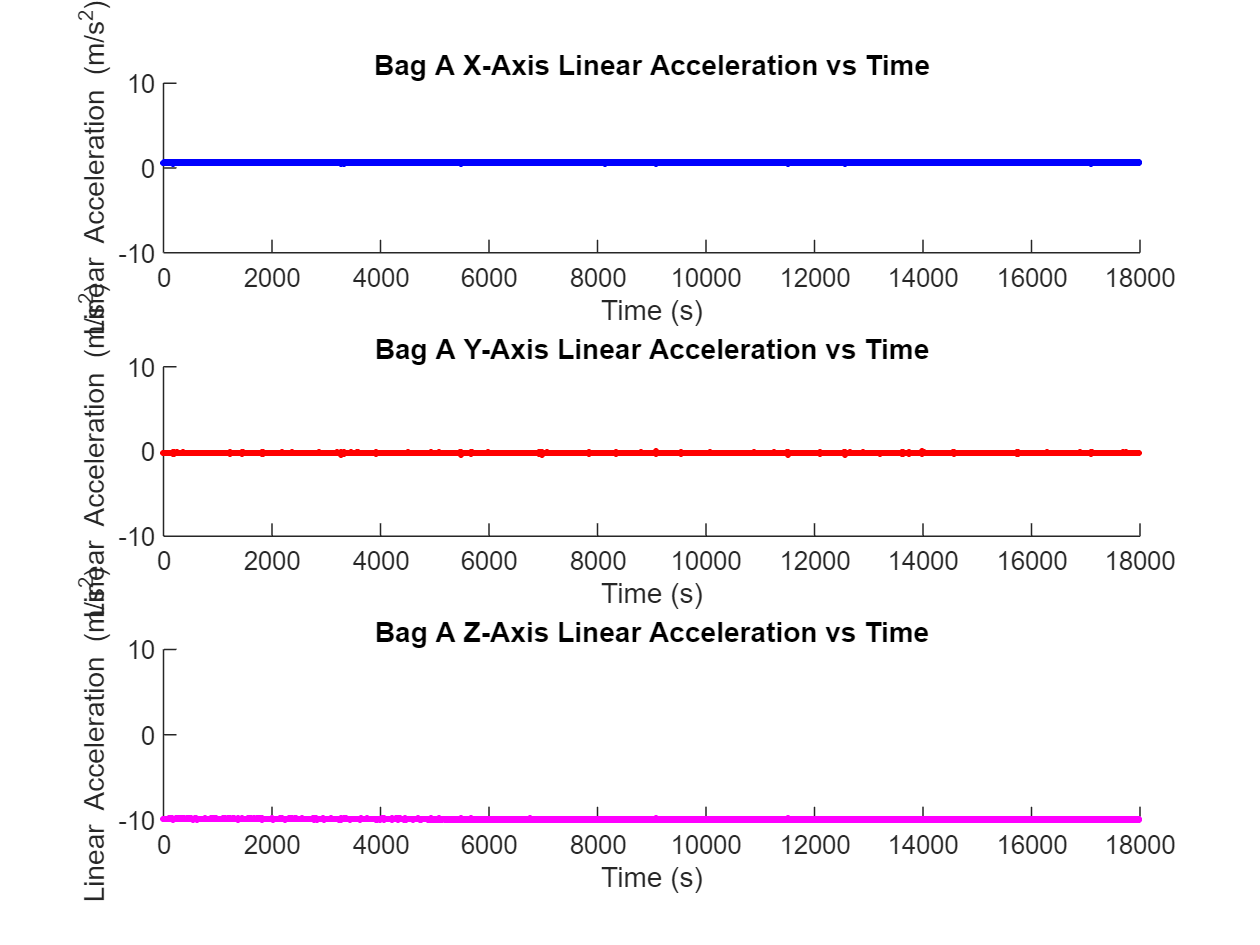

subplot(3,1,1)
scatter(time_A,Data_A(:,7), '.','blue')
title("Bag A X-Axis Linear Acceleration vs Time")
xlabel("Time (s)")
ylabel("Linear Acceleration (m/s^2)")
ylim([-10 10])

subplot(3,1,2)
scatter(time_A,Data_A(:,8), '.','red')
title("Bag A Y-Axis Linear Acceleration vs Time")
xlabel("Time (s)")
ylabel("Linear Acceleration (m/s^2)")
ylim([-10 10])

subplot(3,1,3)
scatter(time_A,Data_A(:,9), '.','magenta')
title("Bag A Z-Axis Linear Acceleration vs Time")
xlabel("Time (s)")
ylabel("Linear Acceleration (m/s^2)")
ylim([-10 10])

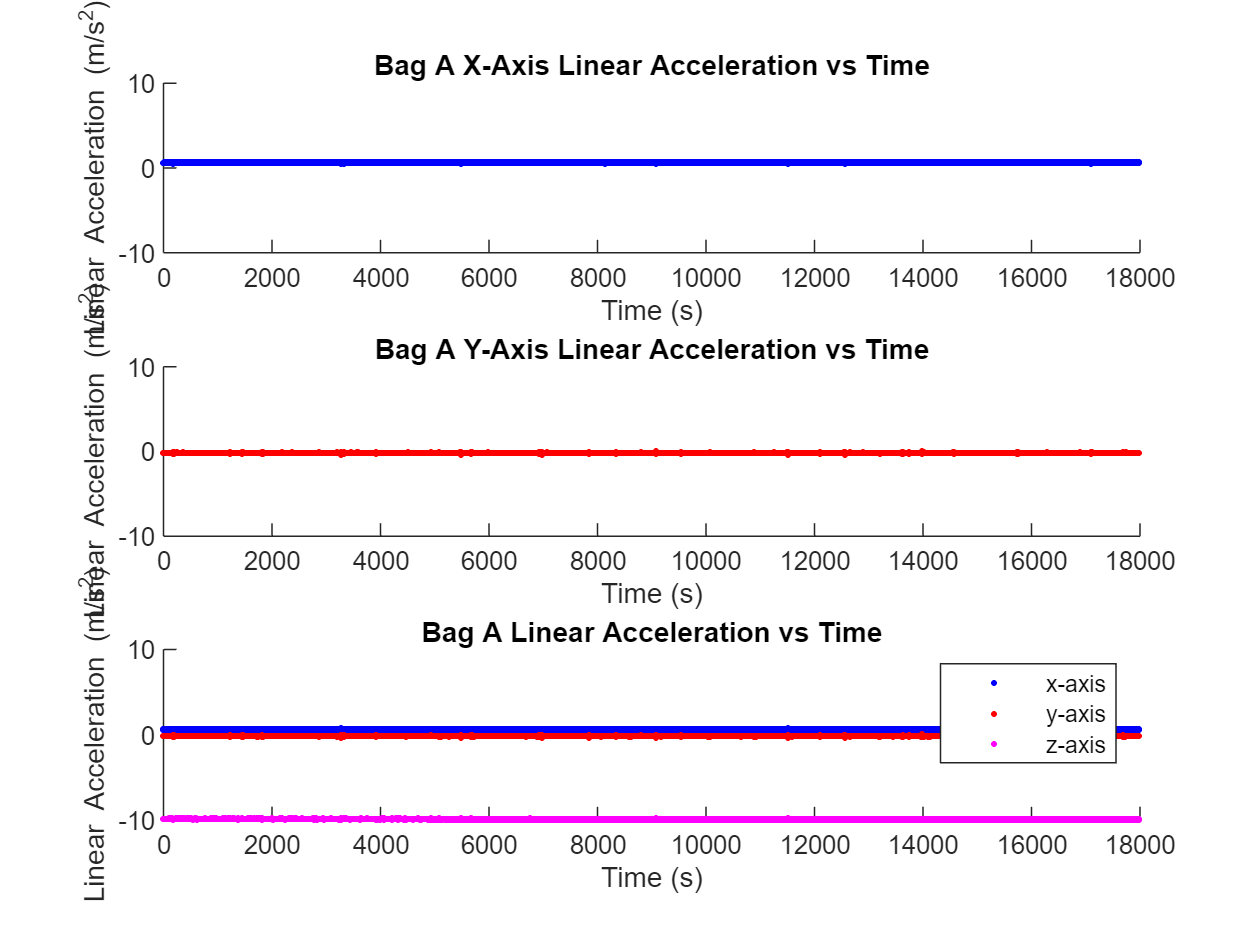


scatter(time_A,Data_A(:,7), '.','blue')
title("Bag A Linear Acceleration vs Time")
xlabel("Time (s)")
ylabel("Linear Acceleration (m/s^2)")
ylim([-10 10])

hold on
scatter(time_A,Data_A(:,8), '.','red')

scatter(time_A,Data_A(:,9), '.','magenta')
hold off
legend('x-axis','y-axis','z-axis')